**ECE537 Programming Assignment 4**

Yuan Sui

X_numsample = 10000;

1) Generate low pass random process X(t)

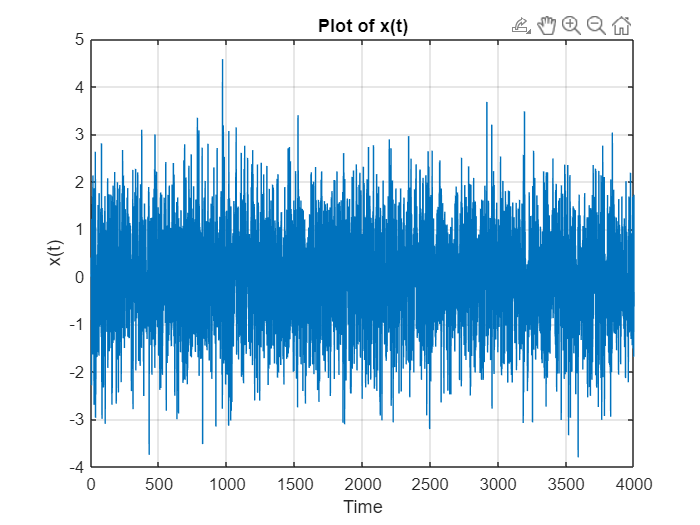

T=1;
tmin = 0;
tmax = 4000*T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

deltat = 0.2 * T;  % Define the time step
x_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

% Loop over the time range
for t = time_arr
    x = X(t, Xk, T);  % Call the function X for each time step
    x_arr = [x_arr, x];  % Append the result to x_arr
end

% Plot x_arr against time_arr
plot(time_arr, x_arr);
xlabel('Time');  % Label for the x-axis
ylabel('x(t)');  % Label for the y-axis
title('Plot of x(t)');  % Title of the plot
grid on;  % Turn on the grid for better visibility

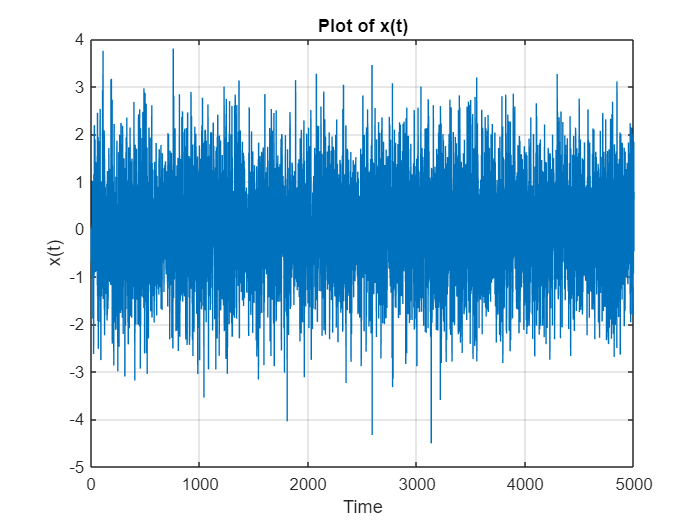

T=1;
tmin = 0;
tmax = 5000*T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

deltat = 0.2 * T;  % Define the time step
x_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

% Loop over the time range
for t = time_arr
    x = X(t, Xk, T);  % Call the function X for each time step
    x_arr = [x_arr, x];  % Append the result to x_arr
end

% Plot x_arr against time_arr
plot(time_arr, x_arr);
xlabel('Time');  % Label for the x-axis
ylabel('x(t)');  % Label for the y-axis
title('Plot of x(t)');  % Title of the plot
grid on;  % Turn on the grid for better visibility

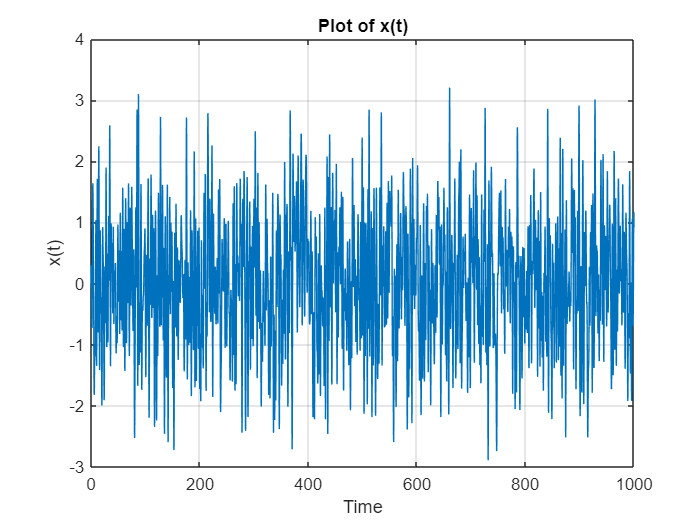

T=1;
tmin = 0;
tmax = 1000*T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

deltat = 0.2 * T;  % Define the time step
x_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

% Loop over the time range
for t = time_arr
    x = X(t, Xk, T);  % Call the function X for each time step
    x_arr = [x_arr, x];  % Append the result to x_arr
end

% Plot x_arr against time_arr
plot(time_arr, x_arr);
xlabel('Time');  % Label for the x-axis
ylabel('x(t)');  % Label for the y-axis
title('Plot of x(t)');  % Title of the plot
grid on;  % Turn on the grid for better visibility

2) Generate filtered low pass random process Y(t)

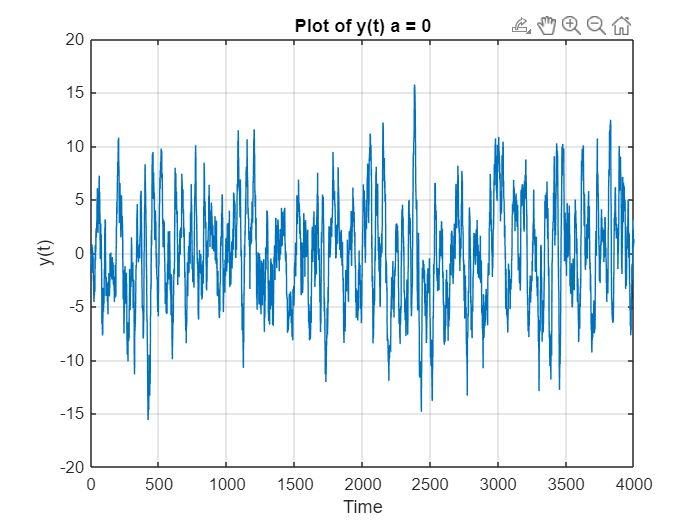

T=1;
tmin = 0;
tmax = 4000*T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

deltat = 0.2 * T;  % Define the time step
y_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

a = 0;
% Loop over the time range
for t = time_arr
    y = Y(t, Xk, T, deltat, a);  % Call the function X for each time step
    y_arr = [y_arr, y];  % Append the result to x_arr
end

% Plot x_arr against time_arr
plot(time_arr, y_arr);
xlabel('Time');  % Label for the x-axis
ylabel('y(t)');  % Label for the y-axis
title('Plot of y(t) a = 0');  % Title of the plot
grid on;  % Turn on the grid for better visibility

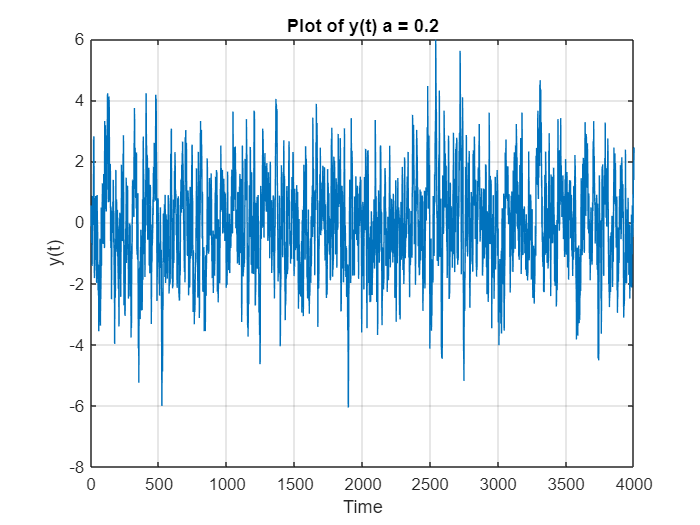

T=1;
tmin = 0;
tmax = 4000*T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

deltat = 0.2 * T;  % Define the time step
y_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

a = 0.2;
% Loop over the time range
for t = time_arr
    y = Y(t, Xk, T, deltat, a);  % Call the function X for each time step
    y_arr = [y_arr, y];  % Append the result to x_arr
end

% Plot x_arr against time_arr
plot(time_arr, y_arr);
xlabel('Time');  % Label for the x-axis
ylabel('y(t)');  % Label for the y-axis
title('Plot of y(t) a = 0.2');  % Title of the plot
grid on;  % Turn on the grid for better visibility

3) Analytically determine the power spectral densit of Y(t). 

After obtaining the PSD of X(t) = Sx(f) and fourier transform of h(t) = H(f)

We can obtain the PSD of Y(t) = Sy(t) = Sx(f)(H(f))^2

Please see derivation detail in supplementary pdf named "Lab4supplement.pdf"

4) Plot FFT a = 0

deltat = 1;
N = 2^13;
a = 0;
X_numsample = 10000;

T=1;
tmin = 0;
tmax = N*T-T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

y_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

% Loop over the time range
for t = time_arr
    y = Y(t, Xk, T, deltat, a);  % Call the function X for each time step
    y_arr = [y_arr, y];  % Append the result to x_arr
end

% Compute the PSD
Fs = 1 / deltat;  % Sampling frequency
L = length(y_arr);  % Length of signal
Y_fft = fft(y_arr);  % Fourier transform of y_arr
P2 = (abs(Y_fft).^2) / L;  % Two-sided PSD
P1 = P2(1:L/2+1);  % Single-sided PSD

f = Fs * (0:(L/2)) / L;  % Frequency array

% Plot the PSD
figure;
plot(f, P1);
title('Power Spectral Density a = 0');
xlabel('Frequency (Hz)');
ylabel('Power (units^2/Hz)');
xlim([0 0.5]);
ylim([0 4000]);
grid on;

a = 0.2

deltat = 1;
N = 2^13;
a = 0.2;

T=1;
tmin = 0;
tmax = N*T-T;

% Generate i.i.d Gaussian random variables with zero mean and variance of 1
Xk = randn(1, X_numsample);  % randn generates normal distribution with mean 0, variance 1

y_arr = [];  % Initialize the array to store the results
time_arr = 0:deltat:tmax;  % Create an array of time values

% Loop over the time range
for t = time_arr
    y = Y(t, Xk, T, deltat, a);  % Call the function X for each time step
    y_arr = [y_arr, y];  % Append the result to x_arr
end

% Compute the PSD
Fs = 1 / deltat;  % Sampling frequency
L = length(y_arr);  % Length of signal
Y_fft = fft(y_arr);  % Fourier transform of y_arr
P2 = (abs(Y_fft).^2) / L;  % Two-sided PSD
P1 = P2(1:L/2+1);  % Single-sided PSD

f = Fs * (0:(L/2)) / L;  % Frequency array

% Plot the PSD
figure;
plot(f, P1);
title('Power Spectral Density a = 0.2');
xlabel('Frequency (Hz)');
ylabel('Power (units^2/Hz)');
xlim([0 0.5]);
ylim([0 300]);
grid on;

4) N=20 

% Define constants
deltat = 0.2;
T = 1;
N = 2^13;
a = 0;

tmin = 0;
tmax = N * T - T;
time_arr = tmin:deltat:tmax; % Array of time values
Fs = 1 / deltat; % Sampling frequency

% Initialize storage for PSDs
psd_all = []; % To store all PSDs

% Repeat the process N times
num_trials = 20; % Number of repetitions
for trial = 1:num_trials
    % Generate i.i.d Gaussian random variables
    Xk = randn(1, 10000);

    % Compute y_arr for the current trial
    y_arr = []; % Reset for each trial
    for t = time_arr
        % Replace Y with your function implementation
        y = Y(t, Xk, T, deltat, a); % Compute y at time t
        y_arr = [y_arr, y]; % Append the result
    end

    % Compute the PSD for this trial
    L = length(y_arr); % Length of the signal
    Y_fft = fft(y_arr); % Compute Fourier Transform
    P2 = (abs(Y_fft).^2) / L; % Compute two-sided PSD
    P1 = P2(1:floor(L/2)+1); % Single-sided PSD
    psd_all = [psd_all, P1]; % Append the PSD to storage
end

% Average the PSDs across trials
psd_avg = mean(psd_all, 2); % Average across columns

% Frequency array
f = Fs * (0:(length(psd_avg)-1)) / length(y_arr);

% Plot the average PSD
figure;
plot(f, psd_avg, 'LineWidth', 2);
title('Average Power Spectral Density (Power/Hz)');
xlabel('Frequency (Hz)');
ylabel('Power (units^2/Hz)');
xlim([0, 0.5]); % Adjust x-axis limit
ylim([0, 400]); % Adjust y-axis limit
grid on;

function x = X(t, Xk, T)
    =]\
    
    % Calculate the position in time
    pos = floor(t / T);
    
    % Determine the start and end index for summing
    kstart = max(1, pos - 5);  % Ensure kstart is within valid index range
    kend = min(length(Xk), pos + 5);  % Ensure kend is within valid index range

    x = 0;  % Initialize the output value
    for k = kstart:kend
        x = x + (Xk(k)) * sinc((t - k * T) / T);
    end
end

function y = Y(t, Xk, T, deltat, a)

    t_floor = floor(t);
    
    y = 0;
    for k=0:1:100
        x = X(t_floor-k*deltat, Xk, T);
        e = exp(-a*(t-t_floor+k*deltat));
        y = y + x*e;
    end

    y = deltat*y;

end
    